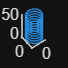

t = 0:1/30:60;

x = sin(t)*10;
y = cos(t)*10;
z = t;

plot3(x,y,z);

positions = [x;y;z]

positions =          0    0.3333    0.6662    0.9983    1.3294    1.6590    1.9867    2.3122    2.6352    2.9552    3.2719    3.5851    3.8942    4.1990    4.4991    4.7943    5.0841    5.3682    5.6464    5.9183    6.1837    6.4422    6.6935    6.9374    7.1736    7.4018    7.6218    7.8333    8.0361    8.2300    8.4147    8.5901    8.7560    8.9121    9.0583    9.1944    9.3204    9.4360    9.5411    9.6356    9.7194    9.7924    9.8545    9.9057    9.9458    9.9749    9.9930    9.9999    9.9957    9.9805
   10.0000    9.9944    9.9778    9.9500    9.9112    9.8614    9.8007    9.7290    9.6465    9.5534    9.4496    9.3353    9.2106    9.0757    8.9307    8.7758    8.6112    8.4370    8.2534    8.0606    7.8589    7.6484    7.4295    7.2023    6.9671    6.7241    6.4737    6.2161    5.9516    5.6805    5.4030    5.1196    4.8305    4.5360    4.2364    3.9322    3.6236    3.3109    2.9946    2.6750    2.3524    2.0271    1.6997    1.3703    1.0394    0.7074    0.3745    0.0413   -0.2

if isfile("positions.txt"); delete positions.txt; end
writematrix(positions)

attitudes = zeros(9, numel(t));

for index = 1:width(attitudes)
attitudes(:,index) = reshape(rotx(t(index)*10) ,9,1);

end


if isfile("attitudes.txt"); delete attitudes.txt; end
writematrix(attitudes)
